% AAE 666 HW8 Exercise 6
% Tomoki Koike
close all; clear all; clc;

% Set constants
theta = 0.5; 
gamma = 10;

% Simulate and plot 
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

res = sim('ex6');

t = res.tout;
x1 = res.x1.signals.values;
x2 = res.x2.signals.values;

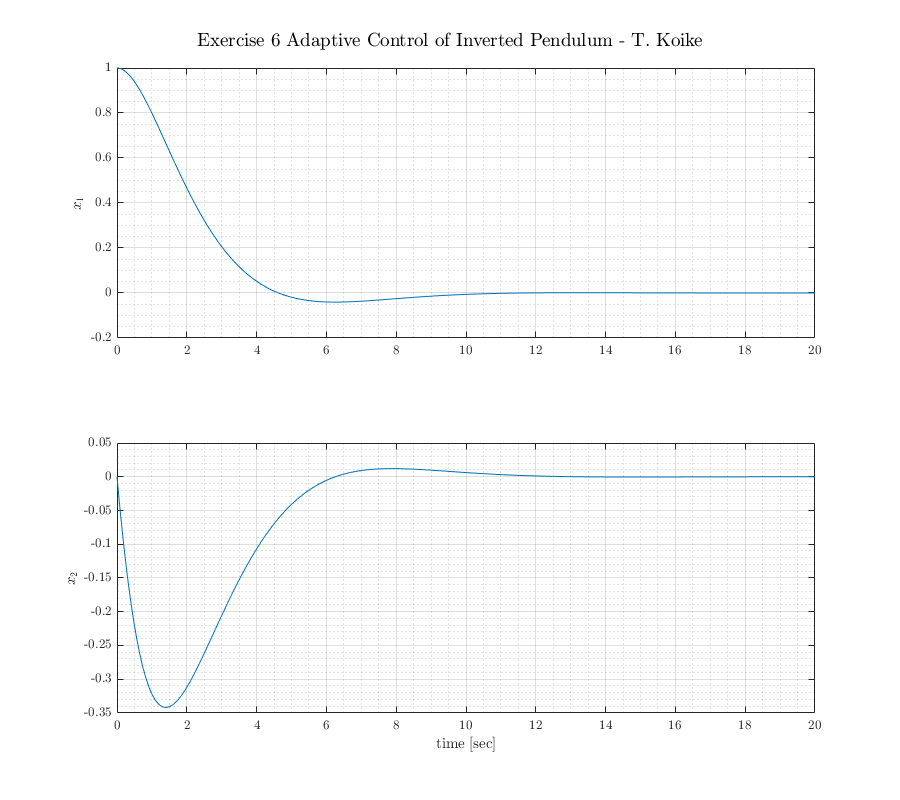

% - Plot 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    subplot(2,1,1)
    plot(t, x1)
    grid on; grid minor; box on;
    ylabel('$x_1$')
    subplot(2,1,2)
    plot(t, x2)
    grid on; grid minor; box on;
    ylabel('$x_2$')
    xlabel('time [sec]')
    title_string = 'Exercise 6 Adaptive Control of Inverted Pendulum - T. Koike';
    sgtitle(title_string)
saveas(fig, 'ex6_adaptCtrl.png')